## **Rozkład normalny standaryzowany**

**Własność **

Jeżeli $X~N\left(\mu ,\sigma \right)$

to zmienna standaryzowana $Z=\frac{X-\mu }{\sigma }$ ma rozkład normalny standaryzowany Z~N(0,1)

**Przykład 1**

Dany jest rozkład N(100,15).

Oblicz $F\left(115\right)=P\left(X\le 115\right)$ z użyciem rozkładu normalnego standaryzowanego.

$P\left(X\le 115\right)$=$P\left(Z=\frac{X-100}{15}\le \frac{115-100}{15}=1\right)$=P$\left(Z\le 1\right)$=F(1)

Z użyciem funkcji **normcdf:**

clear all
close all
clc
clearvars


Zakres wartości

p_z=normcdf(1)

p_z = 0.8413


figure (4)
mu=0

mu = 0

sigma=1

sigma = 1

z=-5:0.01:5 % linspace(-5,5)

z =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);

plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [mu+sigma mu+sigma]

a =      1     1


b = [0 pdf(pd,a(2))]

b =          0    0.2420


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = min(z):0.1:mu+sigma

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


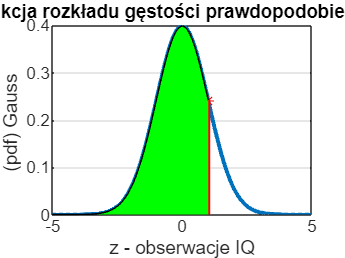

y = pdf(pd,t);
area(t,y,'FaceColor','g');

lub z użyciem funkcji **cdf**:

p_z2=cdf('Normal',1.00,0,1)

p_z2 = 0.8413

odpowiada to w rozkładzie niestandaryzowanym obliczeniu:

p_z3=cdf('Normal',115,100,15)

p_z3 = 0.8413

Przykład 2

Dany jest rozkład normalny (wzrostu w badanej populacji wyrażony w [cm]) o parametrach: N(175,4)

Oblicz $P\left(X\le 184\right)$=F(184)

$P\left(X\le 184\right)$=$P\left(z=\frac{X-175}{4}\le \frac{184-175}{4}=2,25\right)$=P$\left(Z\le 2,25\right)$=F(2,25)

zx=2.25

zx = 2.2500

p_z4=normcdf(zx)

p_z4 = 0.9878

wykres:

figure (5)
mu=0

mu = 0

sigma=1

sigma = 1

z=-5:0.01:5

z =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);

plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [zx zx]

a =     2.2500    2.2500


b = [0 pdf(pd,a(2))]

b =          0    0.0317


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = min(z):0.1:zx

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


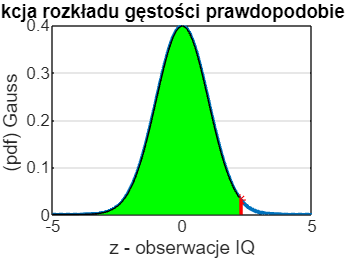

y = pdf(pd,t);
area(t,y,'FaceColor','g');

lub

p_z5=cdf('Normal',2.25,0,1)

p_z5 = 0.9878

odpowiada to w rozkładzie niestandaryzowanym:

p_z6=cdf('Normal',184,175,4)

p_z6 = 0.9878

- Oblicz prawdopodobieństwo znalezienia osób między 175 a 184 cm?

p_z6b=cdf('Normal',2.25,0,1)-cdf('Normal',0,0,1)

p_z6b = 0.4878

Przykład 3

Wyznacz taki punkt x, dla kórego wartość dystrybuanty równa jest 0,5 (rozkład normalny niestandaryzowany)

mu=100

mu = 100

sigma=15

sigma = 15

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.5

p = 0.5000

Funkcja** icdf - ***Inverse cumulative distribution function*

[Funkcja "icdf"](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.icdf.html)

x_prz3=icdf(pd,p)

x_prz3 = 100

Przykład 4

Wyznacz taki punkt z (rozkład normalny standaryzowany), dla kórego wartość dystrybuanty równa jest 0,2 czyli F(z)=0,2

mu=0

mu = 0

sigma=1

sigma = 1

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.2

p = 0.2000

z_p4=icdf(pd,p)

z_p4 = -0.8416


figure (6)
z=-5:0.01:5

z =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);
plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [z_p4 z_p4]

a =    -0.8416   -0.8416


b = [0 pdf(pd,a(2))]

b =          0    0.2800


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = -5:0.1:z_p4

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000


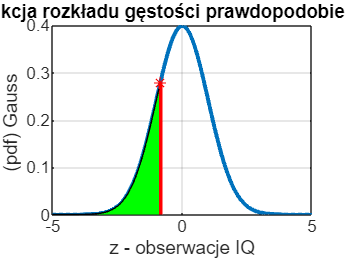

y = pdf(pd,t);
area(t,y,'FaceColor','g');

Przykład 5

Wyznacz taki punkt z, dla kórego wartość dystrybuanty równa jest 0,5 czyli F(z)=0,5.

mu=0

mu = 0

sigma=1

sigma = 1

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.5

p = 0.5000

z_p5=icdf(pd,p)

z_p5 = 0


figure (7)
z=-5:0.01:5

z =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,z);
plot(z,pdf_normal,'LineWidth',2)
xlabel('z - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [z_p5 z_p5]

a =      0     0


b = [0 pdf(pd,a(2))]

b =          0    0.3989


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = -5:0.1:z_p5

t =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000


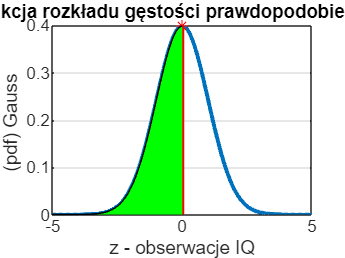

y = pdf(pd,t);
area(t,y,'FaceColor','g');

Przykład 6

Wyznacz taki punkt x - N(100,15), dla kórego wartość dystrybuanty równa jest 0,8 czyli F(z)=0,8 ?

mu=100

mu = 100

sigma=15

sigma = 15

pd=makedist('Normal','mu',mu,'sigma',sigma);
p=0.8

p = 0.8000

x_p6=icdf(pd,p)

x_p6 = 112.6243

wykres

figure (8)
x=0:01:200

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


mu=100

mu = 100

sigma=15

sigma = 15

pd=makedist('Normal','mu',mu,'sigma',sigma);
pdf_normal = pdf(pd,x);
plot(x,pdf_normal,'LineWidth',2)
xlabel('x - obserwacje IQ')
ylabel('(pdf) Gauss ')
title('Funkcja rozkładu gęstości prawdopodobieństwa')
grid on
hold on
a = [x_p6 x_p6]

a =   112.6243  112.6243


b = [0 pdf(pd,a(2))]

b =          0    0.0187


plot(a(2),pdf(pd,a(2)),'r*')
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t = 0:0.1:x_p6

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


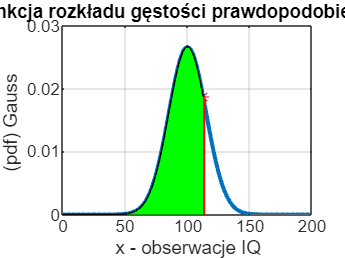

y = pdf(pd,t);
area(t,y,'FaceColor','g');